# a) Transient equilibrium: (ode45 version)

#  
$$^{99}Mo-^{99m}Tc
$$


clc,clearvars,clf

%half lives,hour
tHalfP=65.94; 
tHalfD1=6.04;   
tHalfD2=210000*365*24;
%decay constants
lambdaP=log(2)/tHalfP;  
lambdaD1=log(2)/tHalfD1;
lambdaD2=log(2)/tHalfD2;
%Bateman equations
Bateman=@(t,N)[(-lambdaP*N(1));(lambdaP*N(1)-lambdaD1*N(2));(lambdaD1*N(2))];
%using ode45 for numerical solution of Bateman equations
[t,N]=ode45(Bateman,[0 100],[1/lambdaP 0 0]);

%activity
AP=(lambdaP)*N(:,1); 
AD1=0.88*(lambdaD1)*N(:,2); 
AD2=0.12*(lambdaD2)*N(:,3); 

#### Plotting activity vs. time graph

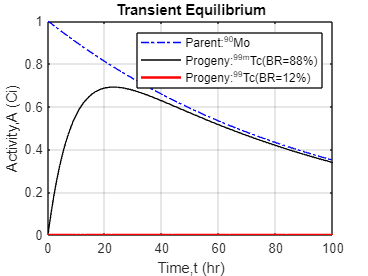

figure(1)
%Mo-90 activity vs. time graph
plot(t,AP,'b-.','linewidth',1) 
hold on
%Tc-99m activity vs. time graph
plot(t,AD1,'k','linewidth',1)
%Tc-99 activity vs. time graph
plot(t,AD2,'r','linewidth',2) 
xlabel('Time,t (hr)')
ylabel('Activity,A (Ci)')
legend('Parent:^{90}Mo','Progeny:^{99m}Tc(BR=88%)','Progeny:^{99}Tc(BR=12%)')
title('Transient Equilibrium')
grid on

#### Plotting Relative no. of atoms vs. time graph

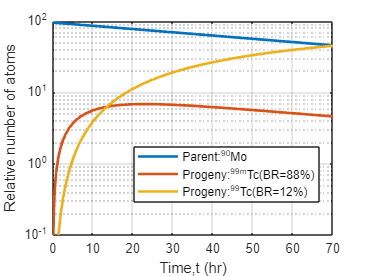

figure(2)

semilogy(t,N(:,1),'linewidth',2)
%axis scaling for better appearance
axis([0 70 10e-2 10e1]) 
hold on
semilogy(t,N(:,2),'linewidth',2)
semilogy(t,N(:,3),'linewidth',2)
xlabel('Time,t (hr)')
ylabel('Relative number of atoms')
legend('Parent:^{90}Mo','Progeny:^{99m}Tc(BR=88%)','Progeny:^{99}Tc(BR=12%)')
grid on

legend("Position", [0.38247,0.27611,0.46734,0.18729])

#### Time when progeny reaches maximum activity

%maximum Tc-99m activity and that specific index I
[maxTcmAct,I]=max(AD1);
%Time to reach maximum activity
tMax=t(I);  
fprintf('Time when ''Tc-99m'' reaches maximum activity= %.4f hr',tMax)

Time when 'Tc-99m' reaches maximum activity= 22.2768 hr